%% fMRI Activation Map
%
% Find the pixels that are dominated by the same period as the reference
% signal and display those on an image of the brain
%
% x is a 122 by 64 by 64 "matrix" containing length 122 time signals
% for a 64 by 64 pixel horizontal slice through the brain.

## Set up workspace

clear
close all

load fmri.mat

x = x(:,:,1) =

     0     0     0     0     1     2     1     1     1     2     0     0     2     0     1     2     3     2     2     4     4     2     2     1     2     1     1     5     5     2     3     2     2     4     2     4     2     4     5     5     1     4     3     2     3     5     2     1     3     1     2     1     2     2     1     1     2     0     1     0     0     0     0     0
     0     0     0     1     1     1     1     3     3     0     2     2     2     1     1     2     2     4     3     4     3     2     4     2     3     3     3     3     5     4     5     4     3     1     5     2     2     4     4     1     1     3     6     3     1     2     2     3     3     1     2     1     4     1     2     1     1     2     1     0     1     0     0     0
     0     0     0     0     1     0     1     1     0     2     2     0     3     1     3     1     1     4     5     3     3     1     2     2     3     2     2     3     4     3     4     4     7     4     1    

ans =       234241
      234242
      234243
      234244
      234245
      234246
      234247
      234248
      234249
      234250


## Find magnitude of periodicity at each pixel

% MATLAB DFT index corresponding to periodic task - from lab activty

% Complete the following line and Uncomment to Run
ref_indx = 7; %<=== complete this line

for i=1:64
    for j=1:64 % pixel index i,j
        
        s = x(:,i,j);  % pixel i,j time series
        
        S = abs(fft(s)); % DFT coeff magnitude of pixel i,j time series
        
        Val(i,j) = S(ref_indx); % DFT coeff mag at reference frequency
        
    end
end

## Create thresholded activation map

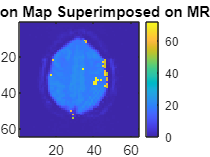

A = zeros(64,64); % initialize activation map

% Complete the following line and Uncomment to Run
thresh = 630; %<=== complete this line

[I] = find(Val>thresh); % I : indices of pixels in Val that exceed thresh
A(I) = 1;  % set "active" pixels to one

% Get anatomy by using pixel values at first time sample
im = reshape(x(1,:,:),64,64); % 64 by 64 matrix im

figure
% Combine a low level MRI (im/50) with high level activation map (A*50) to
% superimpose the activation map on the anatomy in a visually pleasing
% manner.  Other scalings are also acceptable.

imagesc(im/50+A*50) % use imagesc() for MATLAB 2019b or newer
% Note: Use %image(im/50+A*50) for MATLAB 2019a or older
colorbar
title('Activation Map Superimposed on MRI')

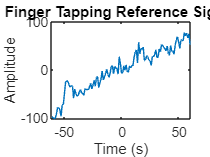

N=122;
t = (-N/2 : (N/2)-1);
x_z = x(:,12,36)-mean(x(:,12,36));

plot(t,x_z)
title('Finger Tapping Reference Signal')
ylabel('Amplitude')
xlabel('Time (s)')

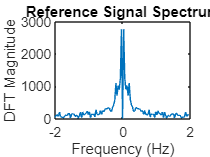

N=122;
fs = 4;
t = (-N/2 : (N/2)-1);
x_z = x(:,12,36)-mean(x(:,12,36));

f_hz = (-N/2 : (N/2)-1) * fs/N;
X = fft(x_z); % Compute fft of time signal
X_shift = fftshift(X); % Shift zero-frequency component to center of spectrum


figure
plot(f_hz, abs(X_shift))
title('Reference Signal Spectrum')
xlabel('Frequency (Hz)')
ylabel('DFT Magnitude')

## (Optional) Devise and Test a better Strategy

% Write Code Below
